## 该代码为基于BP_Adaboost的强预测器预测

%% 清空环境变量
clc
clear


%% 下载数据
load data1 input output

%% 打乱样本顺序
k=rand(1,2000);
[m,n]=sort(k);

%训练样本
input_train=input(n(1:1900),:)';
output_train=output(n(1:1900),:)';

%测试样本
input_test=input(n(1901:2000),:)';
output_test=output(n(1901:2000),:)';

%样本权重
[mm,nn]=size(input_train);
D(1,:)=ones(1,nn)/nn;


%训练样本归一化
[inputn,inputps]=mapminmax(input_train);
[outputn,outputps]=mapminmax(output_train);

K=10;
for i=1:K
    
    %弱预测器训练
    net=newff(inputn,outputn,5);
    net.trainParam.epochs=20;
    net.trainParam.lr=0.1;
    net=train(net,inputn,outputn);
    
    %弱预测器预测
    an1=sim(net,inputn);
    BPoutput=mapminmax('reverse',an1,outputps);
    
    %预测误差
    erroryc(i,:)=output_train-BPoutput;
    
    %测试数据预测
    inputn1=mapminmax('apply',input_test,inputps);
    an2=sim(net,inputn1);
    test_simu(i,:)=mapminmax('reverse',an2,outputps);
    
    
    %调整D值
    Error(i)=0;
    for j=1:nn
        if abs(erroryc(i,j))>0.2  %较大误差
            Error(i)=Error(i)+D(i,j);
            D(i+1,j)=D(i,j)*1.1;
        else
            D(i+1,j)=D(i,j);
        end
    end
    
    %D值归一化
    D(i+1,:)=D(i+1,:)/sum(D(i+1,:));
    
    %计算弱预测器权重
    at(i)=0.5/exp(abs(Error(i)));
end


## 强预测器预测

at=at/sum(at);

## 结果统计

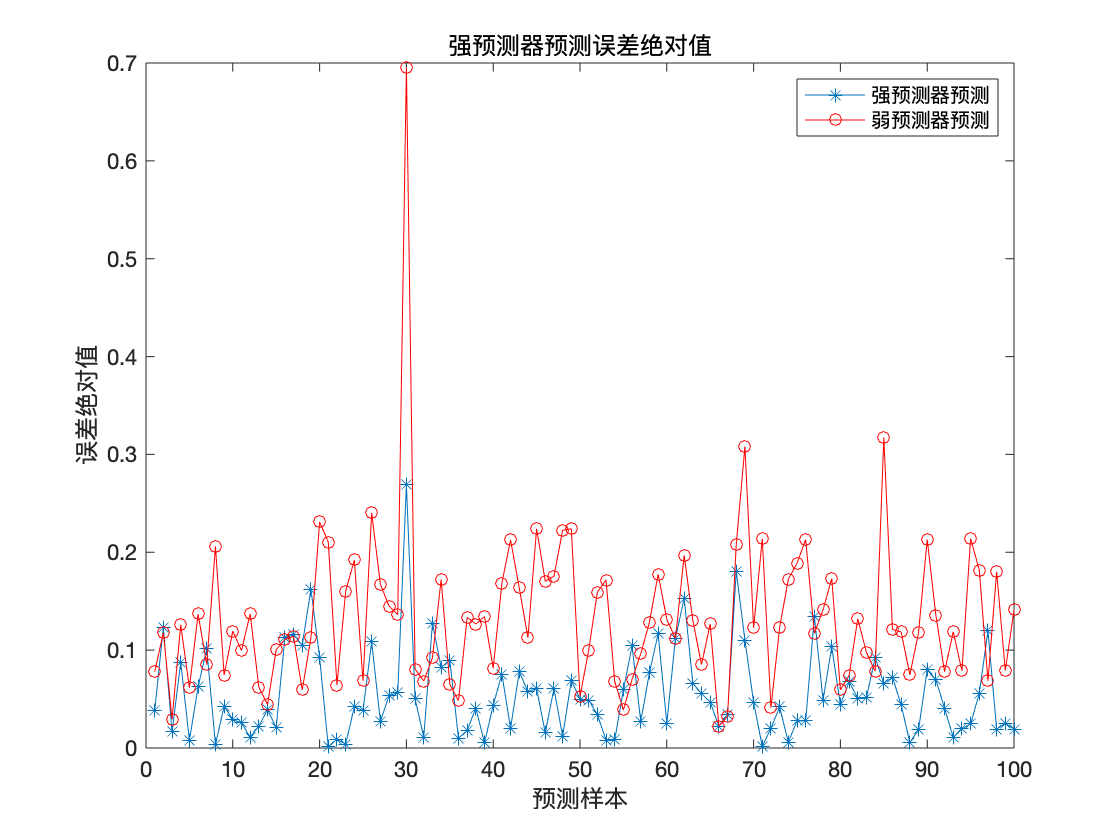

%强分离器效果
output=at*test_simu;
error=output_test-output;
plot(abs(error),'-*')
hold on
for i=1:8
error1(i,:)=test_simu(i,:)-output;
end
plot(mean(abs(error1)),'-or')

title('强预测器预测误差绝对值','fontsize',12)
xlabel('预测样本','fontsize',12)
ylabel('误差绝对值','fontsize',12)
legend('强预测器预测','弱预测器预测')